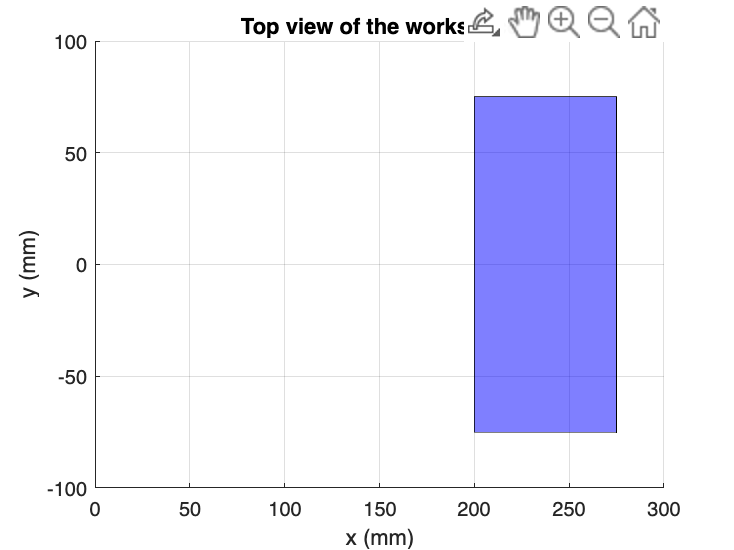

% Define rectangle dimensions
width = 75;
height = 150;
xMin = 200;
xMax = 275;
yMin = -75;
yMax = 75;
zMin = -50;
zMax = 100;


% Create the rectangle coordinates
x = [xMin, xMax, xMax, xMin, xMin];
y = [yMin, yMin, yMax, yMax, yMin];
z = [zMin, zMin, zMax, zMax, zMin];

% Plot the rectangle
figure;
patch(x, y, 'blue', 'FaceAlpha', 0.5);
hold on;

% Set the axis limits and labels
xlim([0, 300]);
ylim([-100, 100]);
xlabel('x (mm)');
ylabel('y (mm)');
title('Top view of the workspace');

% Show gridlines
grid on;

% Display the plot
hold off;

side view

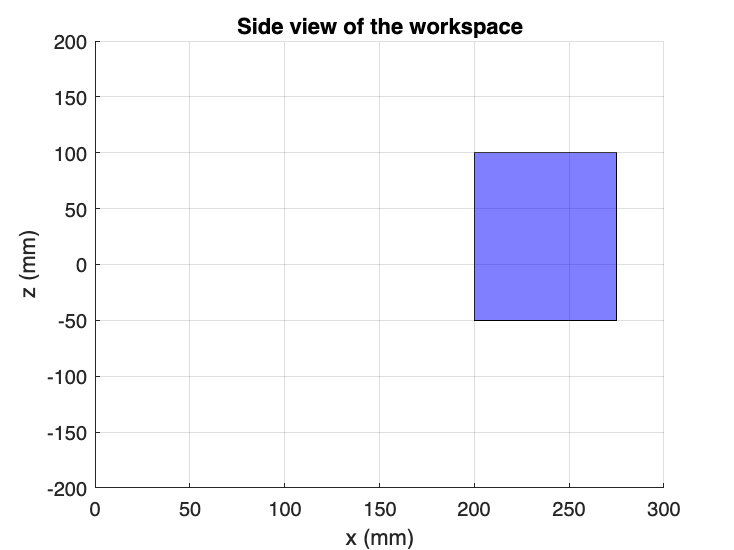

% Plot the rectangle
% figure;
% plot(x, z, 'b-', 'LineWidth', 2);
% hold on;
figure;
patch(x, z, 'blue', 'FaceAlpha', 0.5);
hold on;

% Set the axis limits and labels
xlim([0, 300]);
ylim([-200, 200]);
xlabel('x (mm)');
ylabel('z (mm)');
title('Side view of the workspace');

% Show gridlines
grid on;

% Display the plot
hold off;

3D

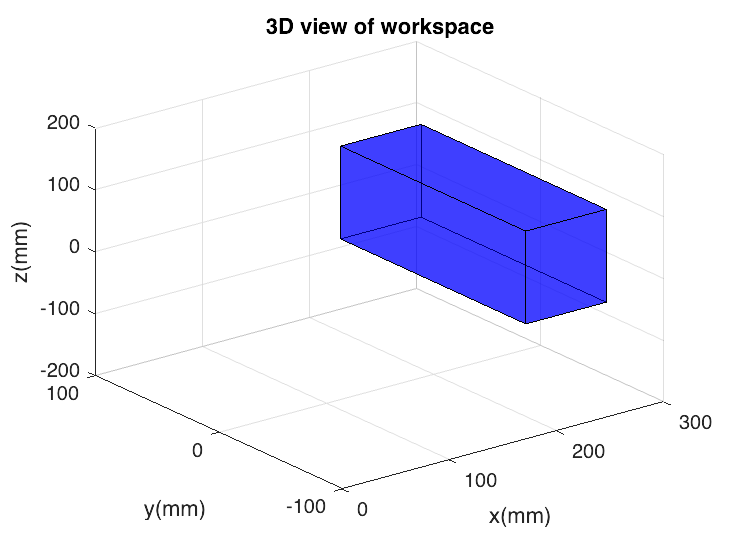

vertices = [
    xMin, yMin, zMin;
    xMin, yMin, zMax;
    xMin, yMax, zMin;
    xMin, yMax, zMax;
    xMax, yMin, zMin;
    xMax, yMin, zMax;
    xMax, yMax, zMin;
    xMax, yMax, zMax
];

faces = [
    1, 2, 4, 3;
    5, 6, 8, 7;
    1, 2, 6, 5;
    3, 4, 8, 7;
    1, 3, 7, 5;
    2, 4, 8, 6
];

figure;
for i = 1:size(faces, 1)
    fill3(vertices(faces(i, :), 1), vertices(faces(i, :), 2), vertices(faces(i, :), 3), 'blue', 'FaceAlpha', 0.5);
    hold on;
end
grid on;
xlabel('x(mm)');
ylabel('y(mm)');
zlabel('z(mm)');
xlim([0, 300]);
ylim([-100, 100]);
zlim([-200, 200]);
title('3D view of workspace');
hold off;